# Include Image in a Report

Use an `mlreportgen.dom.Image` object to specify an image that you want to include in a report. Include the image in the report by appending the `Image` object to the report.

Import the DOM package so that you do not have to use long, fully qualified class names.

import mlreportgen.dom.*

Create a report and add a title for the image using an `mlreportgen.dom.Paragraph` object.

d = Document("myImageReport","docx");

p = Paragraph("Plot 1");
p.Bold = true;
append(d,p);

Save a plot as an image file.

x = 0:pi/100:2*pi;
y = sin(x);
plot(x,y);

saveas(gcf,"myPlot_img.png");

Create an `mlreportgen.dom.Image` object that specifies the path of the image file. Specify that the width and height are 4 inches. Append the `Image` object to the report.

plot1 = Image("myPlot_img.png");
plot1.Width = "4in";
plot1.Height = "4in";
append(d,plot1);

Close and view the report.

close(d);
rptview(d);

Here is the image in the generated report:

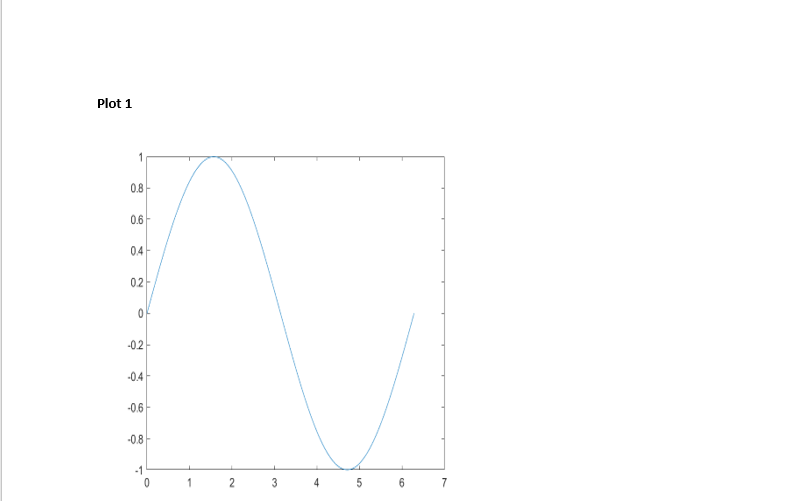

*Copyright 2020 The MathWorks, Inc.*